## Trabalho Avaliativo

### Questão 3

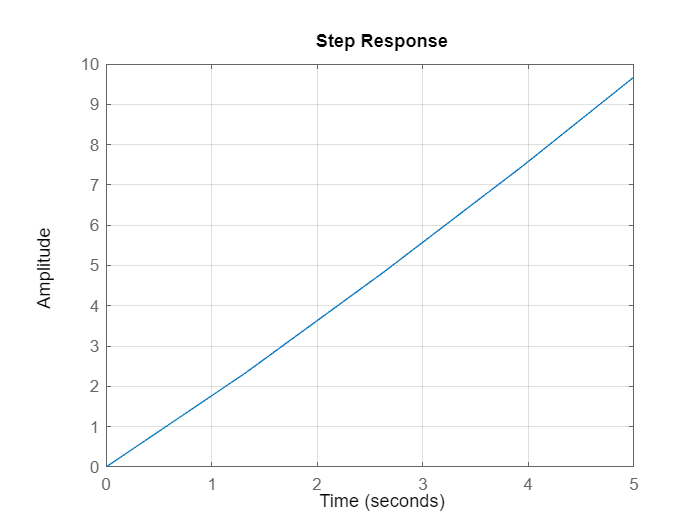

% Calculo da reta tangente ao ponto de inflexao
clear; clc;
import RoboticaBiblioteca.*;
s = tf('s');
M = 1; % Amplitude do degrau
G = 1.2*(exp(-10*s))/((5*s + 1)*(2.5*s + 1))
x = 5;

step(G*M)
xlim([0, x])
grid on;

T = 0.1453

k = 1.9463

Ti = 0.2905

Td = 0.0726

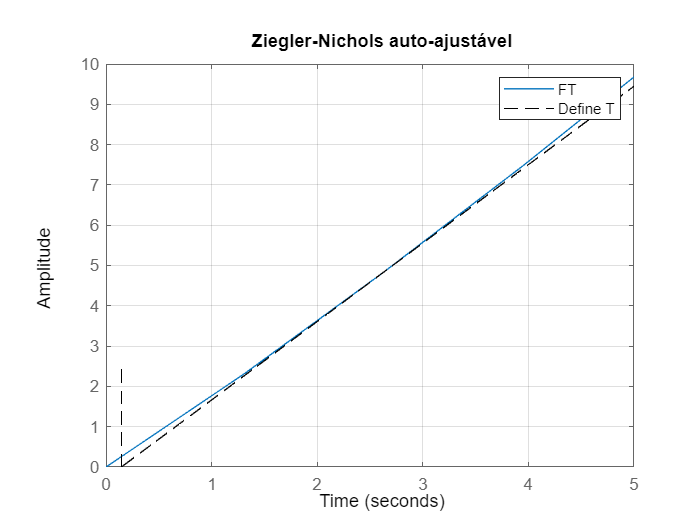

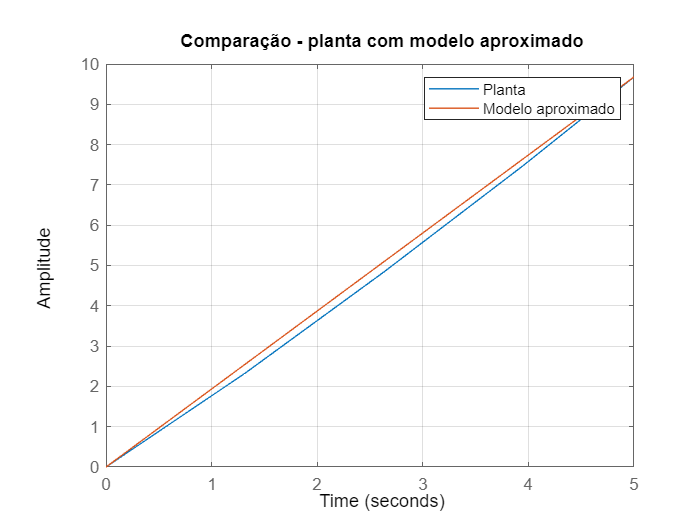

Gapx =
 
                  1.946
  exp(-0.145*s) * -----
                    s
 
Continuous-time transfer function.



Kp = 4.2445

Ki = 14.6094

Kd = 0.3083

% Ziegler-Nichols
%[Gapx, Kp, Ti, Td] = ZNajustavel(G, M, true)
[Gapx, Kp, Ki, Kd] = ZNnaoAjustavel(G, M, x, true)

% Calculo das constantes 

% clear all
% close all
warning off
global kp ki kd erro tempo
options = optimset('Display','iter','TolFun',1e-8,'TolX',1e-8);
x0 = [Kp Ki Kd];
% [x, fval, exitflag, output]= fminsearch(@objective_function_IAE,x0,options)
% [x, fval, exitflag, output]= fminsearch(@objective_function_ITAE,x0,options)
[x, fval, exitflag, output]= fminsearch(@objective_function_MSE,x0,options)

 
 Iteration   Func-count     min f(x)         Procedure
     0            1        0.0015029         
     1            4        0.0015029         initial simplex
     2            9        0.0015029         shrink
     3           14        0.0015029         shrink
     4           19        0.0015029         shrink
     5           24        0.0015029         shrink
     6           29        0.0015029         shrink
     7           34        0.0015029         shrink
     8           39        0.0015029         shrink
     9           44        0.0015029         shrink
    10           49        0.0015029         shrink
    11           54        0.0015029         shrink
    12           59        0.0015029         shrink
    13           64        0.0015029         shrink
    14           69        0.0015029         shrink
    15           74        0.0015029         shrink
    16           79        0.0015029         shrink
    17           84        0.0015029         shrink
    

x =     4.2445   14.6094    0.3083


fval = 0.0015

exitflag = 1

output = struct with fields:
    iterations: 28
     funcCount: 139
     algorithm: 'Nelder-Mead simplex direct search'
       message: 'Optimization terminated:↵ the current x satisfies the termination criteria using OPTIONS.TolX of 1.000000e-08 ↵ and F(X) satisfies the convergence criteria using OPTIONS.TolFun of 1.000000e-08 ↵'
